Fundamentos de control                                                                                                                                                                                                       

# Diagramas de bloques

## De conexiones entre modelos y reducción de bloques

Un sistema en general, y más concretamente un sistema de control, puede constar de varios componentes o elementos. Para representar la función que realiza cada uno de los componentes y sus relaciones (flujo de señales) se emplea un** diagrama de bloques**. En un diagrama de bloques, cada **bloque** representa la operación matemática (expresada como **función de transferencia**) que se aplica a la señal de entrada para producir su salida, y se emplean **flechas** para indicar la dirección del flujo de las señales. La siguiente imagen muestra un ejemplo de estos elementos:

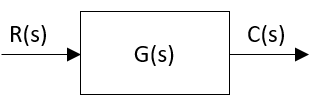

Hay que tener en cuenta que  $C\left(s\right)=G\left(s\right)R\left(s\right)$, o como ya sabemos, $G\left(s\right)=\frac{C\left(s\right)}{R\left(s\right)}$, siendo $G\left(s\right)$la función de transferencia representada por el bloque en cuestión. La siguiente imagen muestra un diagrama de bloques un poco más elaborado. En concreto, a la izquierda se presenta un circuito RLC, y a la derecha el diagrama de bloques que lo modela con entrada $V_i \left(s\right)$ y salida $I_1 \left(s\right)$:

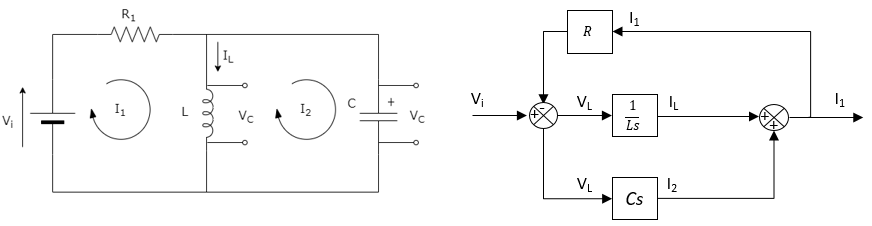

Si se conoce la relación matemática y funcional de cada uno de los componentes del sistema, su diagrama de bloques equivalente puede **reducirse** empleando el **algebra de bloques**, obteniendose un único bloque a analizar.

Dada su simplicidad y versatilidad, los diagramas de bloques resultan una herramienta comúnmente empleada por los ingenieros de control para modelar todo tipo de sistemas. MATLAB, como no podía ser de otra manera, nos facilita una serie de comandos para construir y reducir diagramas de bloques. ¡Vamos allá!

## `1. Conexión entre modelos`

### `1.1 Conexión en serie o cascada`

La **conexión en serie** o **cascada** entre modelos equivale al producto de las correspondientes funciones de transferencia:

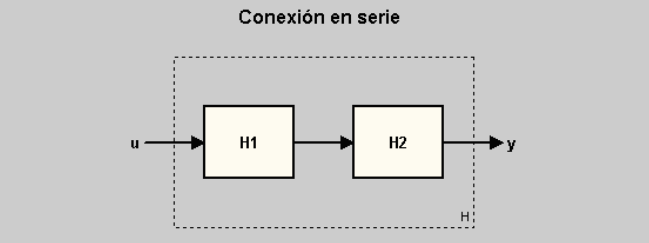

Dados dos modelos, `H1` y `H2`, de dos sistemas conectados en serie, su modelo equivalente,` H`, podría ser obtenido en la forma siguiente:

O de manera equivalente empleando operaciones aritméticas: 

**Tarea 1:** Definir los siguientes modelos $H_1 \left(s\right)$ y $H_2 \left(s\right)$  y realizar su conexión en serie usando ambos métodos, mediante el comando `series` y mediante la multiplicación, comprobando que se obtiene el mismo resultado:


$$H_1 \left(s\right)=\frac{2s+1}{s^2 +5s+3}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;H_2 \left(s\right)=\frac{1}{s+5}$$


% Tu código aquí
H1 = tf([2 1],[1 5 3]);
H2 = tf([1],[1 5]);
H3 = series(H1,H2)

H3 =
 
          2 s + 1
  ------------------------
  s^3 + 10 s^2 + 28 s + 15
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

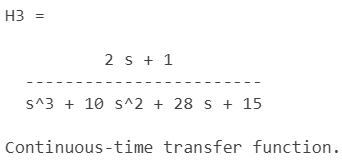

### `1.2 Conexión en paralelo`

La **conexión en paralelo** entre modelos equivale a la suma de las correspondientes funciones de transferencia.

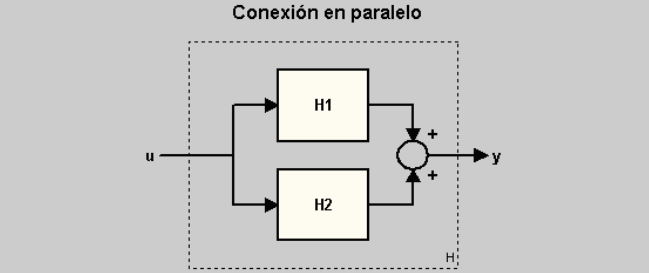

Dados dos modelos, `H1` y `H2`, de dos sistemas conectados en paralelo, su modelo equivalente, `H`, podría ser obtenido en la forma siguiente: 

O de manera equivalente: 

**Tarea 2:** Definir los siguientes modelos y realizar su conexión en paralelo usando tanto `parallel` como aritméticamente, comprobando que se obtiene el mismo resultado:


$$H_1 \left(s\right)=\frac{2s+1}{s^2 +5s+3}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;H_2 \left(s\right)=\frac{1}{s+5}$$


% Tu código aquí
H1 = tf([2 1],[1 5 3]);
H2 = tf([1],[1 5]);
H3 = parallel(H1,H2)

H3 =
 
      3 s^2 + 16 s + 8
  ------------------------
  s^3 + 10 s^2 + 28 s + 15
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

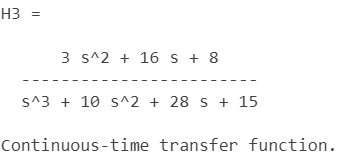

### `1.3 Conexión entre modelos con realimentación`

En este apartado se contempla la clásica conexión de dos modelos constituyendo un sistema realimentado.

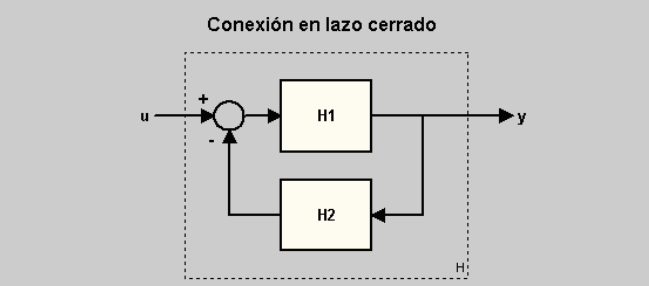

Dados dos modelos, `H1` y `H2`, que constituyen un sistema realimentado con **realimentación negativa**, su modelo equivalente, `H`, podría ser obtenido en la forma siguiente: 

Este procedimiento es equivalente a: 

De igual modo, empleando operaciones aritméticas: 

Dados dos modelos, `H1` y `H2`, que constituyen un sistema realimentado con **realimentación positiva**, su modelo equivalente, *H*, podría ser obtenido en la forma siguiente: 

O de manera equivalente: 

Cabe señalar que, tanto en el uso de las funciones `series`, `parallel` y `feedback` como en los cálculos aritméticos equivalentes a ellas que se acaban de describir, si uno de los modelos intervinientes tiene formato `tf` o `zpk` y el otro modelo es representable por un valor constante, dicho valor se podría usar directamente como parámetro de entrada de la correspondiente función o en el cálculo aritmético en cuestión, sin necesidad de dar también a este modelo un formato `tf` o `zpk`.

Por ejemplo si tenemos dos modelos $H_1 \left(s\right)=3$ y $H_2 \left(s\right)=\frac{2}{s+3}$ en serie:

**Tarea 3:** Definir los siguientes modelos y realizar su conexión con realimentación negativa usando tanto `feedback` como aritméticamente, comprobando que se obtiene el mismo resultado:


$$\textrm{H1}=\frac{s+5}{\left(s+3\right)\left(s+2\right)}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{H2}=\frac{3\left(s+1\right)}{s+5}$$


*Pista: Cuando se obtienen funciones de transferencia fruto de un comando distinto de *`zpk`* o *`tf`*, o usando aritmética de bloques, puede que la función de transferencia resultante tenga factores comunes en su numerador y denominador (esto es, ceros y polos con el mismo valor). Para simplificarlos podéis hacer uso del comando *`minreal`* en la forma siguiente: *`Sysn = minreal(Sys). `*Usa el comando *`help`* para más info*`.`

% Tu código aquí
s = tf('s');
H1 = (s+5)/((s+3)*(s+2));
H2 = (3*(s+1))/(s+5);
HF = feedback(H1,H2);
H = zpk(HF);
H =zpk(H1/(1+H1*H2));
minreal(H)
%Como podemos observar los resulados son los mismos

ans =
 
           (s+5)^2
  -------------------------
  (s+6.646) (s+5) (s+1.354)
 
Continuous-time zero/pole/gain model.
Model Properties


## `2. Agrupación de modelos`

MATLAB permite agrupar modelos de sistemas SISO mediante la construcción de una matriz diagonal de agregación donde las filas son salidas y las columnas son entradas, resultando en un sistema de múltiples entradas y múltiples salidas (MIMO).

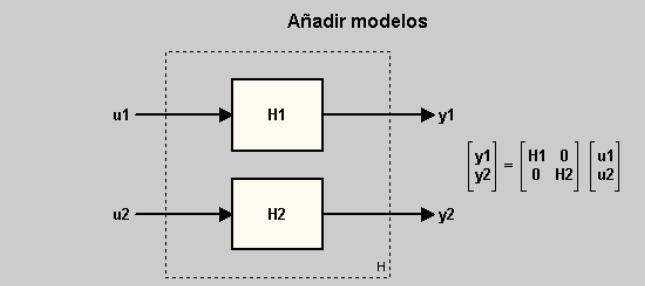

Para agrupar los modelos de dos sistemas SISO, `H1` y `H2`, para constituir el modelo `H` de un sistema con dos entradas y dos salidas en la forma indicada en la figura anterior, se podría actuar en la forma siguiente: 

Como resultado de esta actuación, el valor asignado a H es la matriz de transferencia del correspondiente sistema MIMO:


$$H=\left\lbrack \begin{array}{cc}
\textrm{H1} & 0\\
0 & \textrm{H2}
\end{array}\right\rbrack$$


Un procedimiento similar sería aplicable para obtener modelos de sistemas MIMO generados como agrupación de tres o más sistemas SISO, para lo que habría que añadirlos como parámetros de entrada adicionales al comando `append`.

Es de reseñar que, en el uso del comando `append`, si al menos uno de los modelos intervinientes en la agrupación de sistemas SISO considerada tiene formato `tf` o `zpk` y uno o varios de los restantes modelos involucrados en dicha agrupación es/son representable/s por un valor constante, dicho valor se podría usar directamente como parámetro de entrada de la correspondiente función, sin necesidad de dar también a este/estos modelo/s un formato `tf` o `zpk`.

## `3. Reducción de diagramas de bloques`

MATLAB provee un poderoso comando para reducir un diagrama de bloques arbitrariamente complejo: `connect`. Para aplicar este comando hay que realizar una identificación (numeración creciente) de los bloques del diagrama, para lo que hay que tener en cuenta las siguientes consideraciones:

- Será imprescindible que el diagrama considerado posea, para cada una de las variables de entrada del sistema global, un bloque que tenga a ésta como entrada y, para cada una de las variables de salida del sistema global, un bloque que tenga a ésta como salida. 

- En caso de ser necesario para cumplir estas condiciones, habrá que incorporar, al diagrama de bloques dado, bloques adicionales cuya función de transferencia sea unitaria que, o bien tengan como entrada una de las variables de entrada del sistema global, o bien tengan como salida una de las variables de salida del sistema global. 

- Asimismo, será necesario asignar un número positivo (identificador) a cada uno de los bloques del diagrama resultante tras el cumplimiento de la condición anteriormente indicada. 

La sintaxis de la función connect es la siguiente: 

dónde:

- `sysba`: modelo del sistema MIMO resultante de la agrupación de los modelos de todos los bloques que intervienen en el diagrama considerado. Para su obtención podrá hacerse uso de la función `append`. El orden que debe darse a estos modelos debe coincidir con el de la numeración creciente asignada a sus correspondientes bloques. 

- `input`: vector cuyas componentes son los índices asignados a los bloques que tienen como entrada a una de las variables de entrada del sistema global. 

- `output`: vector cuyas componentes son los índices asignados a los bloques que tienen como salida a una de las variables de salida del sistema global. 

- `q`: matriz de conexión que especifica en su primer elemento de cada fila una entrada de algún sistema de la matriz `sysba` seguido de las salidas interconectadas a él bien sea directamente o a través de un bloque de suma. Las salidas pueden afectarse por un signo + o - de acuerdo al signo con que entran al bloque de suma. En caso de ser necesario, las filas irán rellenas con ceros para que el número de elementos de cada una de ellas sea el mismo. Por ejemplo, la fila $\left\lbrack 1\;\;2\;\;0\;\;0\right\rbrack$indica que el bloque identificado con el número está conectado a la salida del bloque 2, y la fila $\left\lbrack 2\;\;3\;\;4\;-1\right\rbrack$indica que el bloque 2 está conectado a la salida del sumador: salida 3 + salida 4 - salida 1. En algunos casos puede surgir la necesidad de definir bloques unitarios ficticios para evitar que el índice de un determinado bloque aparezca más de una vez en la fila por existir más de una conexión con él.

El resultado de este comando es el modelo global` sysbc`, el cual viene expresado en ecuaciones en el espacio de estados de la forma:

 
$$\begin{array}{l}
\dot{\;\mathrm{x}} =\textrm{Ax}+\textrm{Bu}\\
\;\mathrm{y}=\textrm{Cx}+\textrm{Du}
\end{array}$$


En caso de que se deseara presentar con formato de función de transferencia el modelo global del sistema considerado, bastaría con aplicar, o bien la función `tf`, o bien la función `zpk`, al modelo determinado por el comando `connect``.`

Contado de esta manera, parece un poco rompecabezas, ¿no? ¡Bajémoslo a la tierra con un ejemplito!

Ejemplo:

Reducir el siguiente diagrama de bloques:

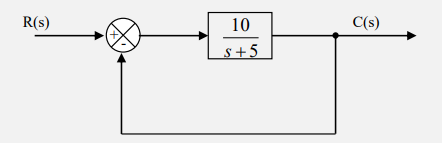

Comenzaremos enumerando los bloques que aparecen en el diagrama y añadiendo los auxiliares necesarios:

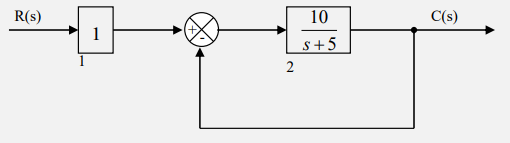

Nos metemos ya en el código...

G1 = 1; % Modelo del bloque 1
G2 = tf(10,[1 5]); % Modelo del bloque 2
sysba = append(G1,G2); % Modelo de sist. con entr. y salidas de bloques//// esta es la forma que tiene matlab de saber que bloque hemos definido como uno y como dos

input = 1; % Indice correspondiente al bloque de entrada
output = 2; % Indice correspondiente al bloque de salida
q = [2 1 -2]; % Matriz de conexion entre bloques
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
    10
  ------
  s + 15
 
Continuous-time transfer function.
Model Properties


**Tarea 4:** Calcule la función de transferencia en bucle cerrado de los sistemas realimentados (con realimentación negativa), esto es:

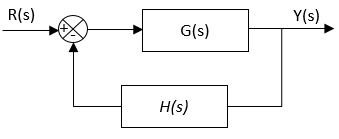

caracterizados por las siguientes funciones de transferencia de la planta, $G_i \left(s\right)$y del factor de realimentación, $H_i \left(s\right)$. Para ello habrán de ser empleados los siguientes procedimientos: 

- Analítico (a mano). 

- Puramente aritmético con modelos creados por MATLAB. 

- Mediante la función `feedback`. 

- Mediante las funciones `append` y `connect`


$$\begin{array}{l}
G_1 \left(s\right)=\frac{s^2 +5s+2}{s^3 +3s^2 +3s+1}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;H_1 \left(s\right)=1;\\
G_2 \left(s\right)=\frac{7s^2 +s+2}{s^3 +s^2 +1}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;H_2 \left(s\right)=\frac{1}{s+1};\\
G_3 \left(s\right)=\frac{s+1}{s^2 +5s}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;H_3 \left(s\right)=\frac{s+2}{s^2 +4s+5}
\end{array}$$


% Tu código aquí
% G1

## 1º PURAMENTE CON MODELOS DE MATLAB

s = tf('s');
G1 = ((s^2)+5*s+2)/((s^3)+3*(s^2)+3*s+1);
H1 = 1;
H =zpk(G1/(1+G1*H1));
minreal(H)

ans =
 
        (s+4.562) (s+1)^3 (s+0.4384)
  ----------------------------------------
  (s+1)^3 (s+0.474) (s^2 + 3.526s + 6.329)
 
Continuous-time zero/pole/gain model.
Model Properties


%Si tachamos los dos terminos repetidos arriba y abajo nos queda la misma
%que usando el comando feedback 

## 2º USANDO EL COMANDO FEEDBACK


H =feedback(G1, H1)

H =
 
      s^2 + 5 s + 2
  ---------------------
  s^3 + 4 s^2 + 8 s + 3
 
Continuous-time transfer function.
Model Properties


H = zpk(H)

H =
 
        (s+4.562) (s+0.4384)
  --------------------------------
  (s+0.474) (s^2 + 3.526s + 6.329)
 
Continuous-time zero/pole/gain model.
Model Properties


## 3º MEDIANTE LAS FUNCIONES APPEND Y CONNECT

E = 1;
S = 1;
G1 = ((s^2)+5*s+2)/((s^3)+3*(s^2)+3*s+1); % Modelo del bloque 2
H1 = 1;  % Modelo del bloque 3(realimentación)
sysba = append(E,G1,H1,S); % Modelo de sist. con entr. y salidas de bloques//// esta es la forma que tiene matlab de saber que bloque hemos definido como uno y como dos

input = 1; % Indice correspondiente al bloque de entrada
output = 2; % Indice correspondiente al bloque de salida
q = [2 1 -3;3 2 0;0 0 0]; % Matriz de conexion entre bloques
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
      s^2 + 5 s + 2
  ---------------------
  s^3 + 4 s^2 + 8 s + 3
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

 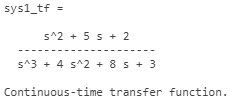

% G2

## 1º PURAMENTE CON MODELOS DE MATLAB

s = tf('s');
G1 = ((7*s^2)+s+2)/((s^3)+(s^2)+1);
H1 = 1/(s+1);
H =tf(G1/(1+G1*H1));
minreal(H)

ans =
 
     7 s^3 + 8 s^2 + 3 s + 2
  -----------------------------
  s^4 + 2 s^3 + 8 s^2 + 2 s + 3
 
Continuous-time transfer function.
Model Properties


## 2º USANDO EL COMANDO FEEDBACK


H =feedback(G1, H1)

H =
 
     7 s^3 + 8 s^2 + 3 s + 2
  -----------------------------
  s^4 + 2 s^3 + 8 s^2 + 2 s + 3
 
Continuous-time transfer function.
Model Properties


## 3º MEDIANTE LAS FUNCIONES APPEND Y CONNECT

E = 1;
S = 1;
G1 = ((7*s^2)+s+2)/((s^3)+(s^2)+1);
H1 = 1/(s+1);
sysba = append(E,G1,H1,S); 

input = 1; % Indice correspondiente al bloque de entrada
output = 2; % Indice correspondiente al bloque de salida
q = [2 1 -3;3 2 0;0 0 0]; % Matriz de conexion entre bloques
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
     7 s^3 + 8 s^2 + 3 s + 2
  -----------------------------
  s^4 + 2 s^3 + 8 s^2 + 2 s + 3
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

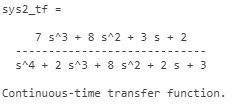

% G3

## 1º PURAMENTE CON MODELOS DE MATLAB

s = tf('s');
G1 = ((s+1)/((s^2)+5*s));
H1 = (s+2)/((s^2)+4*s+5);
H =tf(G1/(1+G1*H1));
minreal(H)

ans =
 
       s^3 + 5 s^2 + 9 s + 5
  -------------------------------
  s^4 + 9 s^3 + 26 s^2 + 28 s + 2
 
Continuous-time transfer function.
Model Properties


## 2º USANDO EL COMANDO FEEDBACK


H =feedback(G1, H1)

H =
 
       s^3 + 5 s^2 + 9 s + 5
  -------------------------------
  s^4 + 9 s^3 + 26 s^2 + 28 s + 2
 
Continuous-time transfer function.
Model Properties


## 3º MEDIANTE LAS FUNCIONES APPEND Y CONNECT

E = 1;
S = 1;
G1 = ((s+1)/((s^2)+5*s));
H1 = (s+2)/((s^2)+4*s+5);
sysba = append(E,G1,H1,S); 

input = 1; % Indice correspondiente al bloque de entrada
output = 2; % Indice correspondiente al bloque de salida
q = [2 1 -3;3 2 0;0 0 0]; % Matriz de conexion entre bloques
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
       s^3 + 5 s^2 + 9 s + 5
  -------------------------------
  s^4 + 9 s^3 + 26 s^2 + 28 s + 2
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

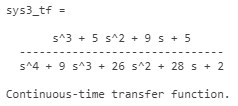

**Tarea 5:** En las siguientes tareas, calcule la función de transferencia global de los sistemas realimentados caracterizados por los diagramas de bloques dados. Para ello habrán de ser empleados los siguientes procedimientos:

- Analítico (mediante técnicas basadas en el álgebra de bloques).

- Mediante las funciones `append` y `connect`.

Pista: Como puede verse, junto a cada diagrama de bloques se muestra la correspondiente solución.

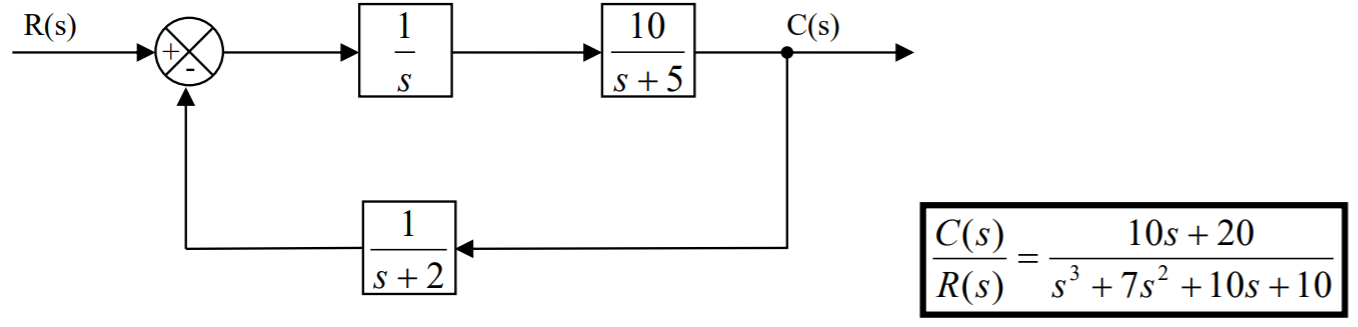

% Tu código aquí
s = tf('s');
E = 1;
S = 1;
G1 = (10/((s^2)+5*s));
H1 = 1/((s+2));
sysba = append(E,G1,H1,S); 

input = 1; % Indice correspondiente al bloque de entrada
output = 2; % Indice correspondiente al bloque de salida
q = [2 1 -3;3 2 0;4 2 0]; % Matriz de conexion entre bloques
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
         10 s + 20
  -----------------------
  s^3 + 7 s^2 + 10 s + 10
 
Continuous-time transfer function.
Model Properties


**Tarea 6:**

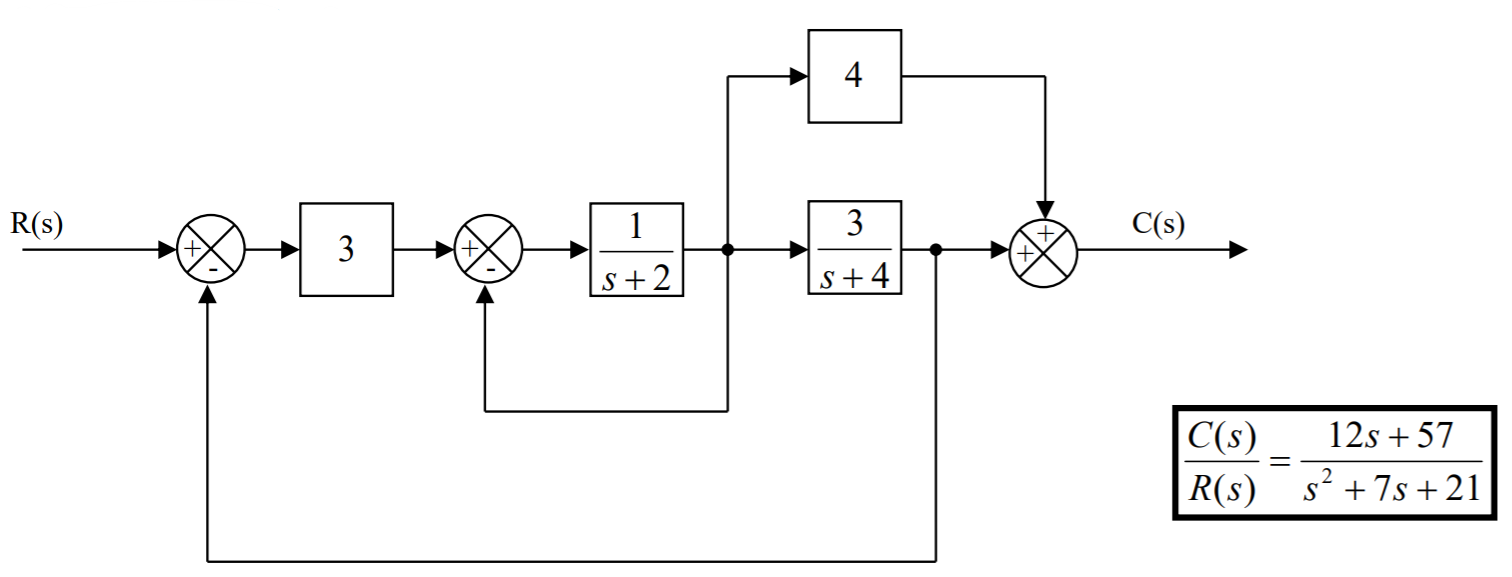

% Tu código aquí
s = tf('s');
E = 1;
S = 1;
G1 = 3;
G2 = 1/(s+2);
G3 = 3/(s+4);
H1 = 4;
sysba = append(E,G1,G2,G3,H1,S); 

input = 1; % Indice correspondiente al bloque de entrada
output = 6; % Indice correspondiente al bloque de salida
q = [2 1 -4 0;3 2 -3 0;4 3 0 0;5 3 0 0;6 4 5 0]; % Matriz de conexion entre bloques
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
    12 s + 57
  --------------
  s^2 + 7 s + 21
 
Continuous-time transfer function.
Model Properties


**Tarea 7:**

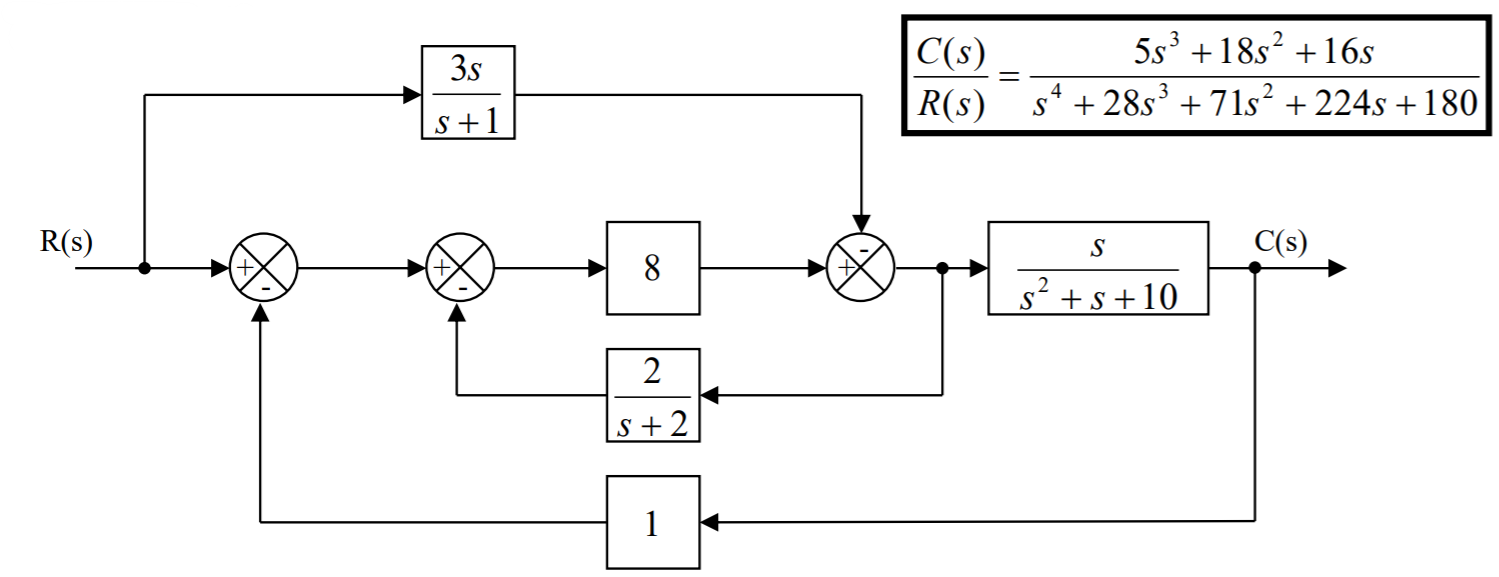

% Tu código aquí
s = tf('s');
E = 1;
S = 1;
G1 = 1;
G2 = 8;
G3 = s/((s^2)+s+10);
H3 = 2/(s+2);
H2 = 1;
H1 = 3*s/(s+1);
sysba = append(E,G1,H1,G2,G3,H3,H2,S);  

input = 1; % Indice correspondiente al bloque de entrada
output = 8; % Indice correspondiente al bloque de salida
q=[2 1 -7; 3 1 0; 4 2 -6; 5 4 -3; 6 4 -3; 7 5 0;8 5 0];
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
   5 s^3 + 18 s^2 + 16 s + 6.161e-16
  -----------------------------------
  s^4 + 28 s^3 + 71 s^2 + 224 s + 180
 
Continuous-time transfer function.
Model Properties


**Tarea 8:**

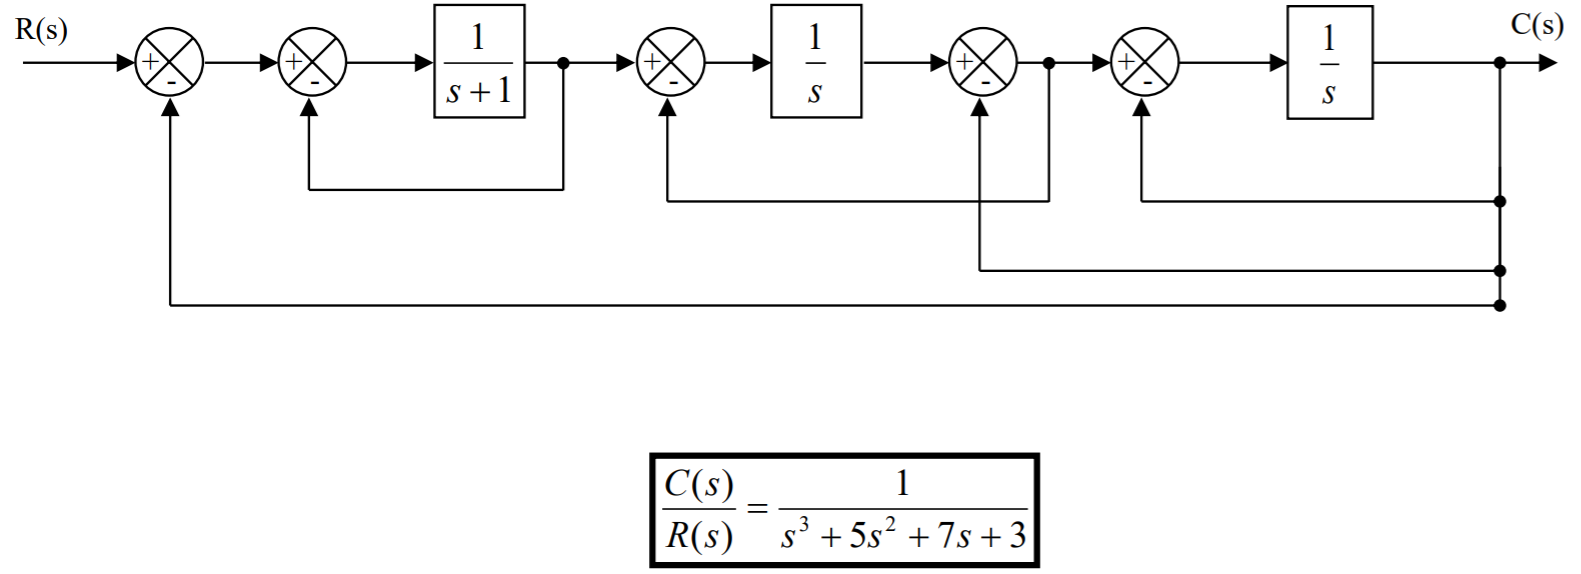

% Tu código aquí
s = tf('s');
E = 1;
S = 1;
G1 = 1;
G2 = 1/(s+1);
G3 = 1/s;
G4 = 1;
G5 = 1/s;
sysba = append(E,G1,G2,G3,G4,G5,S);  

input = 1; % Indice correspondiente al bloque de entrada
output = 7; % Indice correspondiente al bloque de salida
q=[2 1 -6; 3 2 -3; 4 3 -5; 5 4 -6; 6 5 -6; 7 6 0];
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
            1
  ---------------------
  s^3 + 5 s^2 + 7 s + 3
 
Continuous-time transfer function.
Model Properties


**Tarea 9:**

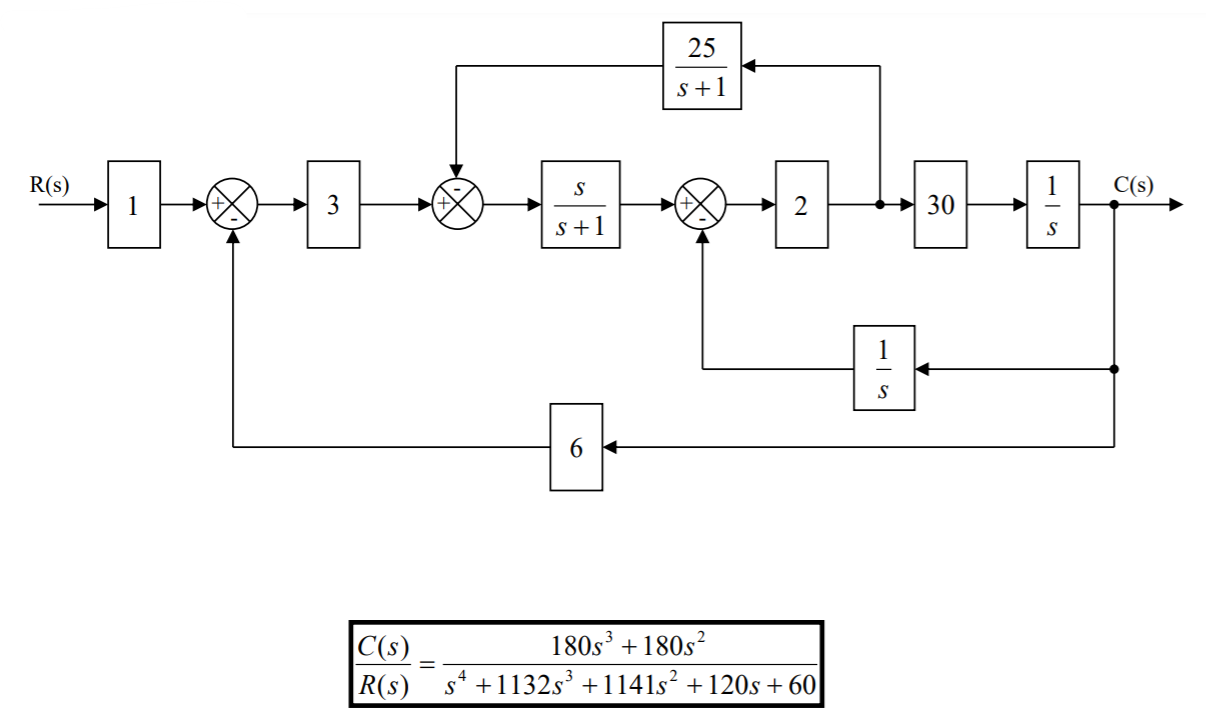

% Tu código aquí
s = tf('s');
E = 1;
S = 1;
G2 = 1;
G3 = 3;
G4 = s/(s+1);
G5 = 2;
G6 = 30;
G7 = 1/s;
H8 = 25/(s+1);
H9 = 1/s;
H10 = 6;
sysba = append(E,G2,G3,G4,G5,G6,G7,H8,H9,H10,S);  

input = 1; % Indice correspondiente al bloque de entrada
output = 11; % Indice correspondiente al bloque de salida
q=[2 1 0; 3 2 -10; 4 3 -8; 5 4 -9; 6 5 0; 7 6 0; 8 5 0; 9 7 0; 10 7 0; 11 7 0];
sysb_ss = connect(sysba,q,input,output); % Modelo global en ss.
G = tf(sysb_ss); % Modelo global equivalente en formato tf
% Modelo global simplificado (definitivo) con formato tf
G = minreal ( G ) 

G =
 
  180 s^3 + 180 s^2 + 1.385e-12 s + 6.049e-30
  -------------------------------------------
    s^4 + 1132 s^3 + 1141 s^2 + 120 s + 60
 
Continuous-time transfer function.
Model Properties
